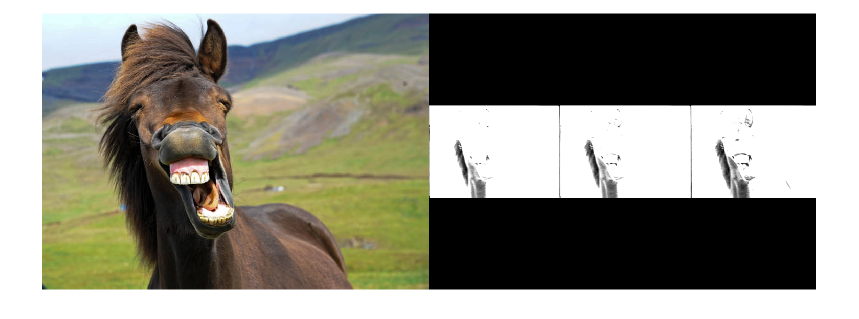

% Load image
image = imread('horse.jpg');

% Apply directional blur
blurred_image = directional_blur(image);

% Show original and blurred images
montage({image, blurred_image});

function blurred_image = directional_blur(image)

% Get image dimensions
[rows, cols] = size(image);

% Generate random angle for blur direction
angle = 2*pi*rand;

% Define blur kernel size
kernel_size = 11; % Adjust this value as needed

% Create Gaussian kernel with specified size
sigma = kernel_size/3;
x = -kernel_size/2:kernel_size/2;
kernel = exp(-x.^2/(2*sigma^2));

% Rotate kernel based on random angle
rot_kernel = imrotate(kernel, rad2deg(angle), 'bilinear');

% Pad image to avoid boundary artifacts
padded_image = padarray(image, [floor(kernel_size/2) floor(kernel_size/2)], 'both');

% Apply convolution with rotated kernel
blurred_image = imfilter(padded_image, rot_kernel, 'conv');

% Crop padded image back to original size
blurred_image = blurred_image(1:rows, 1:cols);

end